## Boas Práticas

clear all;      % Limpa as variáveis
close all;      % fecha as figuras
clc;            % limpa a tela

## Lendo os arquivos de áudio

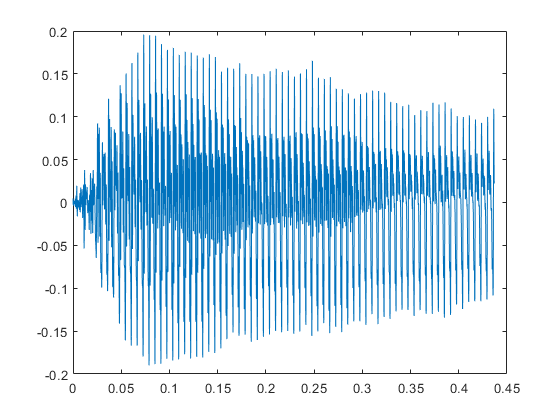

[VG_a, fs_a] = audioread("a1.wav");

% Extraindo o canal esquerdo
VG_a = VG_a(:, 1);


%%%%%%% Ouvindo o sinal

sound(VG_a,fs_a);

Na      = length(VG_a);          % número de pontos da vogal /a/
Ta      = inv(fs_a);             % taxa de amostragem da vogal /a/
Da      = (Na - 1)*Ta;          % Duração do sinal da vogal /a/
tempoa  = linspace(0,Da,Na);     % tempo da vogal /a/

plot(tempoa,VG_a)


% Janelamento do sinal

janela = hamming(Na);
VG_aj = VG_a.*janela;

sound(VG_aj,fs_a);


## Transformada De Fourier (Obter Formantes e Frequência Fundamental)

fft_vogal = abs(fftshift(fft(VG_aj)));

freq = linspace(-fs_a/2, fs_a/2, Na);

[~, index] = max(fft_vogal);
fundamental_frequency = abs(freq(index))       % FREQUÊNCIA FUNDAMENTAL 

fundamental_frequency = 159.1355

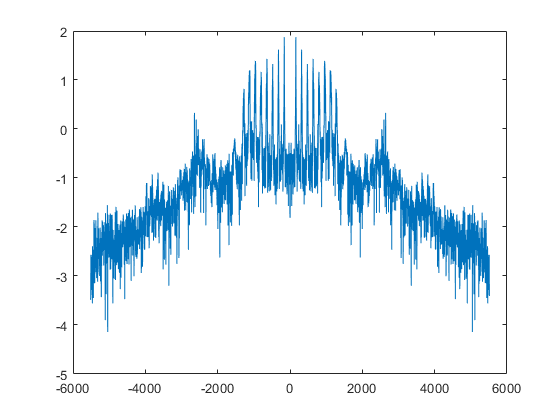

fundamental_T = 1/(fundamental_frequency);      % Período Fundamental
fator_fft = fundamental_frequency*0.9;          % Fator de segurança para findpeaks fft

%%%%%%%%%%%%% Obtendo os formantes da vogal %%%%%%%%%%%%%

fft_log = log10(fft_vogal);     % Base logaritmica para melhor compreensão dos picos

plot(freq, fft_log);

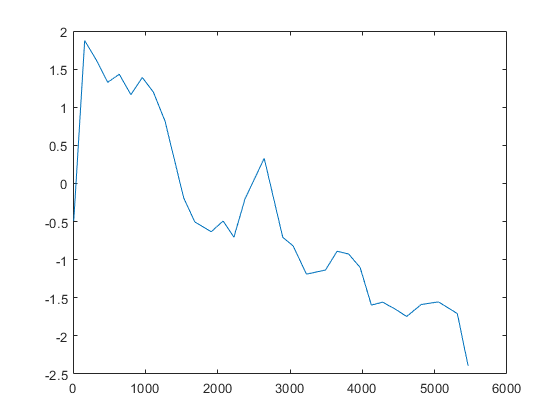


% Isolando apenas os valores positivos de frequência e seus respectivos
% valores de energia

indice_positivo = freq > 0;
freq_positivo = freq(indice_positivo);
fft_log_pos = fft_log(indice_positivo);

% obtendo os macropicos
[picos_x,picos_y] = findpeaks(fft_log_pos, freq_positivo,'MinPeakDistance',fator_fft);

plot(picos_y,picos_x)

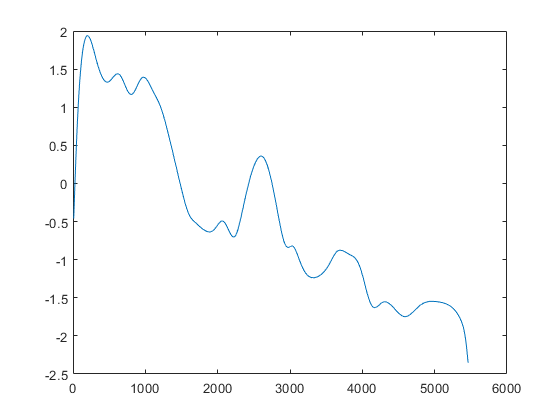


% Utilização do comando interp1

resolucao_atual = length(picos_x);
resolucao_desejada = 5 * resolucao_atual;

indices_atual = 1:resolucao_atual;
indices_desejados = linspace(1, resolucao_atual, resolucao_desejada);

peaks_y_resampled = interp1(indices_atual, picos_y, indices_desejados, 'spline');
peaks_x_resampled = interp1(indices_atual, picos_x, indices_desejados, 'spline');

% Ajustando uma curva suave aos pontos originais
ajuste_curva = fit(peaks_y_resampled', peaks_x_resampled', 'smoothingspline');

% Definindo a resolução desejada para a função contínua
resolucao_desejada = 600;

% Criando um vetor de valores suavemente espaçados para a variável independente
x_continuo = linspace(min(peaks_y_resampled), max(peaks_y_resampled), resolucao_desejada);

% Avaliando a curva ajustada nos valores contínuos de x
y_continuo = feval(ajuste_curva, x_continuo);

% Plot da função contínua
plot(x_continuo, y_continuo);


derivada = diff(y_continuo);
segunda_derivada = diff(derivada);

x_continuo1 = x_continuo(1:end-1);
x_continuo2 = x_continuo(1:end-2);

%plot(x_continuo1,derivada)
%plot(x_continuo2,segunda_derivada)

% Indices de maximo e minimo
indices_mudanca_sinal = (find(diff(sign(derivada)) ~= 0)+1);

% Pontos em x
pontos_mudanca_sinal = x_continuo(indices_mudanca_sinal);

% Verificando se a segunda derivada é negativa nos pontos de mudança de sinal
pontos_segunda_derivada_negativa = x_continuo2(indices_mudanca_sinal(2:end)); % Ignorando o primeiro ponto (frequencia fundamental)

% Acessando os valores correspondentes no vetor x

% Formantes (em HZ)
formants = pontos_segunda_derivada_negativa(segunda_derivada(indices_mudanca_sinal(2:end)) < 0)

formants = 	1.0e+03 *

    0.6201    0.9751    2.0582    2.6042    3.0229    3.6964    4.3062    4.9615


## Encontrando os picos no tempo

fator_tempo = fundamental_T*0.9;            % Fator de segurança para findpeaks tempo
deslocamento = 1000*fundamental_T;

[picos,indice_picos] = findpeaks(VG_aj,tempoa,'MinPeakDistance',fator_tempo);

% Isolando do 31° ao 32° pico

inicio_index = (find(tempoa == indice_picos(31)));
fim_index = (find(tempoa == indice_picos(32)));

distancia_index = fim_index - inicio_index;
deslocamento = distancia_index/10;          % Parâmetro de ajuste de deslocamento para isolar o sinal

inicio_index = inicio_index - deslocamento;
fim_index = fim_index - deslocamento;

tempo_isolado = tempoa(inicio_index:fim_index);

sinal_isolado = VG_aj(inicio_index:fim_index);

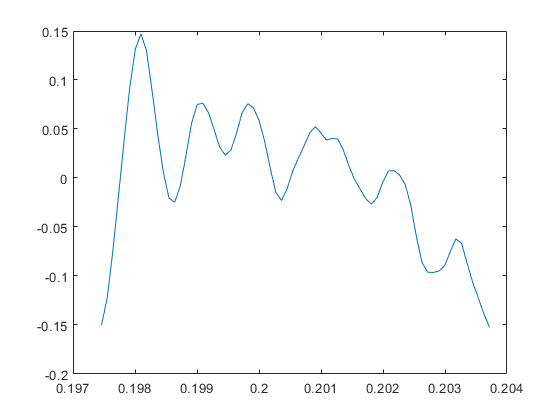



plot(tempo_isolado,sinal_isolado)

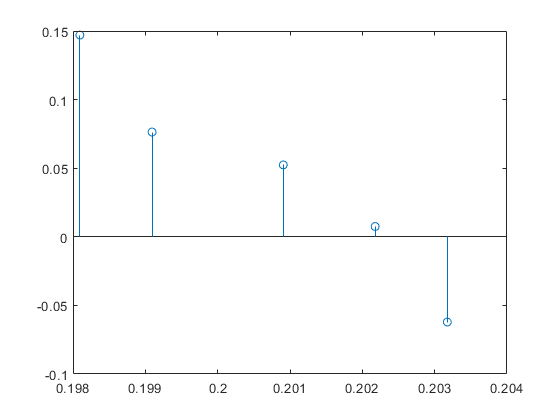

 


fator_min = 0.9*(0.001);

[vexp,texp] = findpeaks(sinal_isolado,tempo_isolado,'MinPeakDistance',fator_min);

stem(texp,vexp)


% Ajustando exponencial que descreva o amortecimento da senoide
 

f = fit(texp',vexp,'exp1')

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =   4.451e+56  (-1.185e+59, 1.193e+59)
       b =      -668.1  (-2015, 678.7)

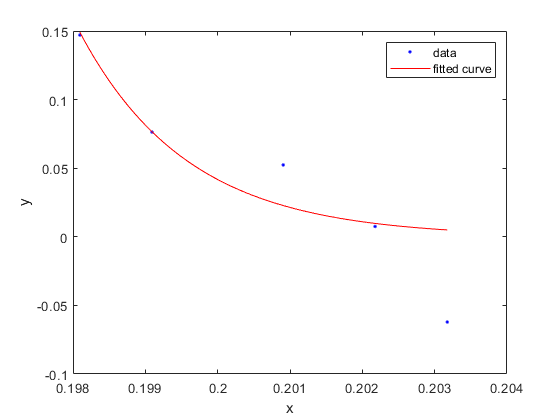


plot(f,texp',vexp)


x=[0 4.451e56 -668 1000]';

Y_new = x(1) + x(2).*exp(x(3).*tempo_isolado).*sin(2*pi*x(4).*tempo_isolado)

Y_new =     0.0570   -0.0685   -0.1590   -0.1914   -0.1624   -0.0879    0.0046    0.0851    0.1309    0.1320    0.0933    0.0309   -0.0337   -0.0807   -0.0981   -0.0840   -0.0462    0.0012    0.0428    0.0668    0.0679    0.0485    0.0167   -0.0165   -0.0410   -0.0503   -0.0434   -0.0243    0.0000    0.0215    0.0341    0.0350    0.0252    0.0090   -0.0081   -0.0208   -0.0258   -0.0224   -0.0127   -0.0003    0.0108    0.0174    0.0180    0.0131    0.0048   -0.0039   -0.0105   -0.0132   -0.0116   -0.0067


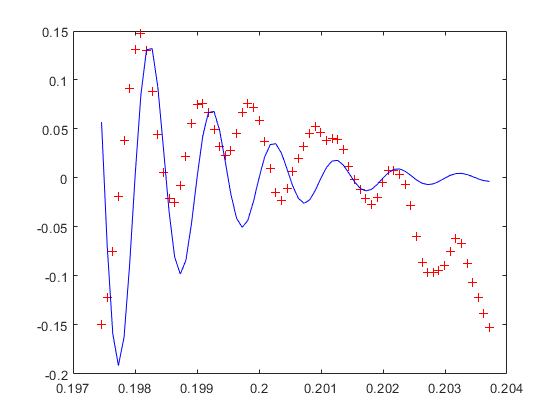

plot(tempo_isolado,sinal_isolado,'+r',tempo_isolado,Y_new,'b')


clear('tf')

k = x(2)*2*pi*x(4);
p1 = x(3) + j*2*pi*x(4);
p2 = x(3) - j*2*pi*x(4);
z = [];

Gvoz = zpk(z,[p1 p2],k)

Gvoz =
 
         2.7966e+60
  ------------------------
  (s^2 + 1336s + 3.992e07)
 
Continuous-time zero/pole/gain model.



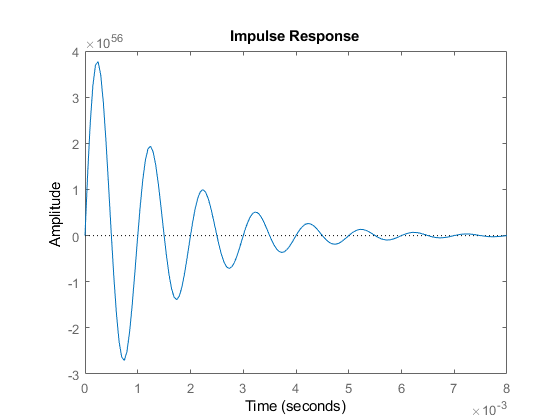

impulse(Gvoz)